# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 17-Apr-2024 13:41:33

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load("/Users/petertso/Documents/params_2024_04_17__13_41_29.mat");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = featureInputLayer(30,"Name","featureinput","Normalization","rescale-zero-one","NormalizationDimension","all");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = fullyConnectedLayer(15,"Name","fc");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = reluLayer("Name","relu");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = fullyConnectedLayer(15,"Name","fc_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","multiplication");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = reluLayer("Name","relu_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = fullyConnectedLayer(15,"Name","fc_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","multiplication_1")
    reluLayer("Name","relu_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(3,"Name","depthcat")
    batchNormalizationLayer("Name","batchnorm")
    fullyConnectedLayer(30,"Name","fc_3")
    dropoutLayer(0.5,"Name","dropout")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    fullyConnectedLayer(15,"Name","fc_4")
    dropoutLayer(0.5,"Name","dropout_1")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","depthcat_1")
    fullyConnectedLayer(2,"Name","fc_5")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"featureinput","fc");
lgraph = connectLayers(lgraph,"featureinput","fc_1");
lgraph = connectLayers(lgraph,"featureinput","fc_2");
lgraph = connectLayers(lgraph,"featureinput","fc_4");
lgraph = connectLayers(lgraph,"fc","relu");
lgraph = connectLayers(lgraph,"fc","multiplication/in1");
lgraph = connectLayers(lgraph,"relu","depthcat/in1");
lgraph = connectLayers(lgraph,"fc_1","multiplication/in2");
lgraph = connectLayers(lgraph,"multiplication","relu_2");
lgraph = connectLayers(lgraph,"multiplication","multiplication_1/in1");
lgraph = connectLayers(lgraph,"relu_2","depthcat/in2");
lgraph = connectLayers(lgraph,"fc_2","multiplication_1/in2");
lgraph = connectLayers(lgraph,"relu_1","depthcat/in3");
lgraph = connectLayers(lgraph,"relu_3","depthcat_1/in2");
lgraph = connectLayers(lgraph,"relu_4","depthcat_1/in1");

## Plot Layers

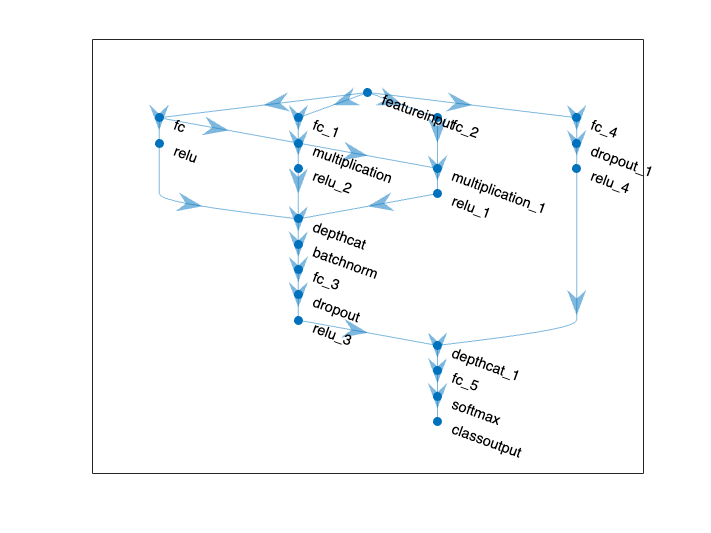

plot(lgraph);